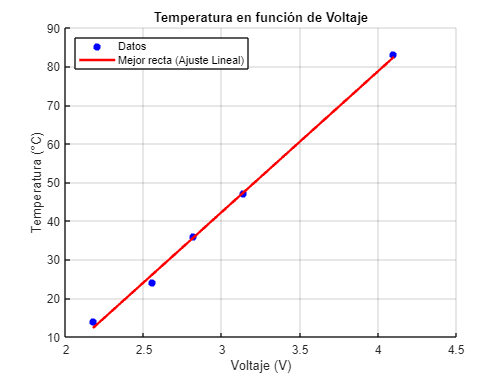

% Datos
temperatura = [14 24 36 47 83]; % Temperatura en °C
voltaje = [2.175 2.555 2.82 3.14 4.1]; % Voltaje en V

% Graficar los puntos
figure;
scatter(voltaje, temperatura, 'b', 'filled');
hold on;

% Ajuste de la recta con regresión lineal
p = polyfit(voltaje, temperatura, 1); % Ajuste lineal de los datos
voltaje_fit = linspace(min(voltaje), max(voltaje), 100); % Valores para la línea
temperatura_fit = polyval(p, voltaje_fit); % Evaluar la recta ajustada

% Graficar la recta de mejor ajuste
plot(voltaje_fit, temperatura_fit, 'r-', 'LineWidth', 2);

% Configuración del gráfico
title('Temperatura en función de Voltaje');
xlabel('Voltaje (V)');
ylabel('Temperatura (°C)');
legend('Datos', 'Mejor recta (Ajuste Lineal)', 'Location', 'NorthWest');
grid on;
hold off;